%% initialize environments
clc;
clear variables;

%% set file paths
recorded_file_path = "mic.wav";
time_streched_pulses_file_path = "tsp.wav";

%% generate AudioFileManipulator instance and confirm properties
recorded_file = AudioFileManipulator(recorded_file_path);
recorded_file.load_properties();
recorded_file.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : mic.wav
output_file_path : default.wav
signal shape : (301445, 1)
sample_rate: 44100 [Hz]
             Filename: 'D:\名城大学\研究室\演習\data\tsp\mic.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 301445
             Duration: 6.8355
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 24

--------------------------------------------



time_streched_pulses_file = AudioFileManipulator(time_streched_pulses_file_path);
time_streched_pulses_file.load_properties();
time_streched_pulses_file.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : tsp.wav
output_file_path : default.wav
signal shape : (301445, 1)
sample_rate: 44100 [Hz]
             Filename: 'D:\名城大学\研究室\演習\data\tsp\tsp.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 301445
             Duration: 6.8355
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 24

--------------------------------------------



%% generate TimeStrechedPulses instance and confirm properties
TSPInstance = TimeStrechedPulses(time_streched_pulses_file.signal, recorded_file.signal);

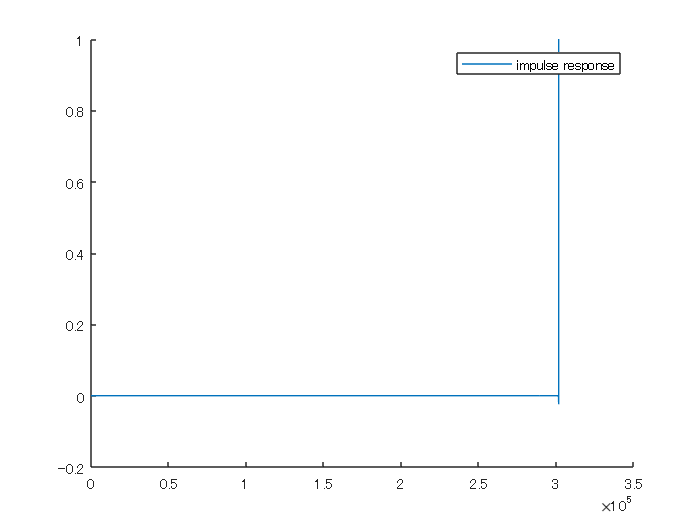

hold on;
legend;
plot(TSPInstance.impulse_response, "DisplayName", "impulse response");